(b) Determinati functiile rationale R11(x) si R22(x) pentru f(x) = e^x . Reprezentati grafic si comparati graficele lui f(x) = e^x , R11 si R22. Sunt satisfacatoare aceste aproximatii rationale ale lui e^x pe [−1, 1]? Cum se comporta comparativ cu seriile Maclaurin trunchiate din problemele precedente?

syms x

% custom function
R11 = customPade(@(x) exp(x), 4, 4, x);
simplifyFraction(R11)

$$ans = \frac{x^{4}+20\,x^{3}+180\,x^{2}+840\,x+1680}{x^{4}-20\,x^{3}+180\,x^{2}-840\,x+1680}$$


% built in function 
pade(exp(x), x, 'Order', [sym(4), sym(4)])

$$ans = \frac{x^{4}+20\,x^{3}+180\,x^{2}+840\,x+1680}{x^{4}-20\,x^{3}+180\,x^{2}-840\,x+1680}$$

syms x

% custom function
R22 = customPade(@(x) exp(x), 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{x^{2}+6\,x+12}{x^{2}-6\,x+12}$$


% built in function 
pade(exp(x), x, 'Order', [sym(2), sym(2)])

$$ans = \frac{x^{2}+6\,x+12}{x^{2}-6\,x+12}$$

Grafic

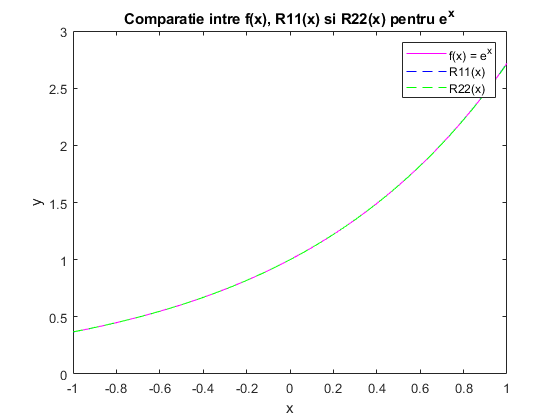

x_vals = linspace(-1, 1, 1000);
f_vals = exp(x_vals);
R11_vals = double(subs(R11, x, x_vals));
R22_vals = double(subs(R22, x, x_vals));

plot(x_vals, f_vals, 'm-', x_vals, R11_vals, 'b--', x_vals, R22_vals, 'g--');
legend('f(x) = e^x', 'R11(x)', 'R22(x)');
xlabel('x');
ylabel('y');
title('Comparatie intre f(x), R11(x) si R22(x) pentru e^x');

R22(x) e o aproximare mai buna decat R11(x) datorita gradului mai mare al polinoamelor. Seriile Maclaurin trunchiate aproximeaza functia intr-un interval restrans in jurul originii, in timp ce funcțiile rationale obtinute prin aproximarea Pade pot aproxima functia pe un interval mai mare. De obicei aproximarea Pade pe un interval, este mai precisa decât seria Maclaurin.

c) Repetati pentru aproximarile R22(x) si R31(x) ale functiei g(x) = ln(1 + x).

syms x

% custom function
R22 = customPade(@(x) log(1+x), 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{3\,\left(x^{2}+2\,x\right)}{x^{2}+6\,x+6}$$

% built in function 
pade(log(1+x), x, 'Order', [sym(2), sym(2)])

$$ans = \frac{3\,x\,\left(x+2\right)}{x^{2}+6\,x+6}$$

syms x

% custom function
R31 = customPade(@(x) log(1+x), 3, 1, x);
simplifyFraction(R31)

$$ans = \frac{-x^{3}+6\,x^{2}+24\,x}{6\,\left(3\,x+4\right)}$$


% built in function 
pade(log(1+x), x, 'Order', [sym(3), sym(1)])

$$ans = \frac{x\,\left(-x^{2}+6\,x+24\right)}{6\,\left(3\,x+4\right)}$$

Grafic

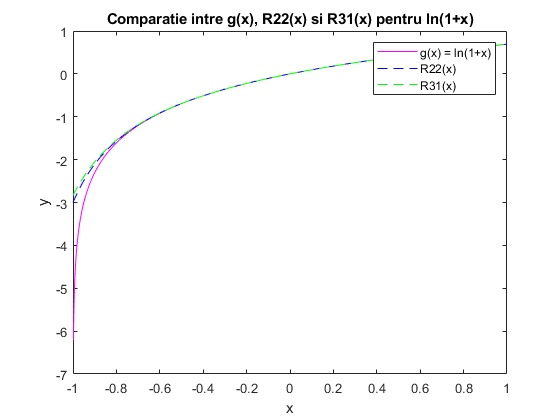

x_vals = linspace(-1, 1, 1000);
g_vals = log(1+x_vals);
R22_vals = double(subs(R22, x, x_vals));
R31_vals = double(subs(R31, x, x_vals));

plot(x_vals, g_vals, 'm-', x_vals, R22_vals, 'b--', x_vals, R31_vals, 'g--');
legend('g(x) = ln(1+x)', 'R22(x)', 'R31(x)');
xlabel('x');
ylabel('y');
title('Comparatie intre g(x), R22(x) si R31(x) pentru ln(1+x)');